# Neural Networks

## What are neural networks?

**Neural networks** are a set of algorithms that are inspired by neural circuits in the brain. These algorithms can be computationally intensive, and have recently exploded in popularity due to advances in computing technology. 

Neural networks work by taking linear combinations of predictors to construct new representations of our features. Non-linear functions are applied to the new features to model the potential non-linearity in the dataset. This family of learning methods can be used for classification and regression problems.

### Modern applications of neural networks

Neural networks have been applied to several real-world problems, from[ determining medical diagnoses by classifying images](https://towardsdatascience.com/medical-diagnosis-with-a-convolutional-neural-network-ab0b6b455a20) to [training a self driving car](https://towardsdatascience.com/deep-learning-for-self-driving-cars-7f198ef4cfa2) to [biomedical text mining for extracting relevant patient information](https://medium.com/@Petuum/applying-neural-networks-to-biomedical-text-mining-fe655270c12). The main advantages of neural networks are the following:

- They can detect nonlinear relationships and interactions between predictor variables

- The mathematics underpinning neural networks relies less on statistical assuptions we usually impose in other models

- Neural networks are modular, and many architectures are available to model different problems

### Common components and notation of a neural network

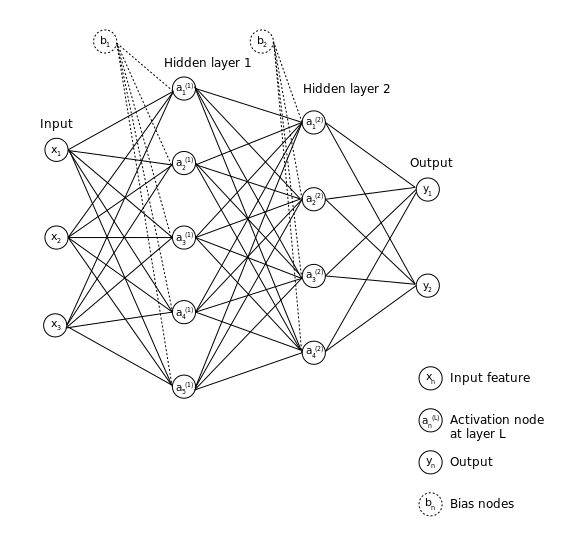

There are [several flavors of neural network architectures](https://medium.com/cracking-the-data-science-interview/a-gentle-introduction-to-neural-networks-for-machine-learning-d5f3f8987786), each one having their own advantages and disadvantages for solving different problems. The diagram above illustrates a **feed-forward neural network**, where information flows forward from the input to the output, and no information feeds back into the network. 

#### The input layer

Each node in the **input layer** represents a feature in the training data ($X_{\textrm{train}}$). In our data array, each column while each edge corresponds to a **weight** vector. Further, we can choose to add more flexibility into the model by introducing some **bias** values. When we move forward in our computations, we'll be solving equations that are analagous to linear regression expression $X^T \cdot \mathrm{weights}+\mathrm{bias}$.

#### The hidden layer(s)

The hidden layer is where the new values are stored from taking linear combinations of features from the input layer and applying non-linear transformations. These nodes are are known as **activation nodes**, and they represent a single new feature. 

A neural network with a single hidden layer is known as a **shallow neural network**. However, we can add more complexity in the model by adding more hidden layers. Neural networks with more than 1 hidden layer are known as **deep neural networks** (DNNs), and the application of DNNs is known as **deep learning**. 

**The output layer**

From the last hidden layer, the values are transformed once more to the **output layer**. Here, we can use rules to turn these values into labels for a classification problem, or keep the raw values / probabilities in a regression problem. 

To illustrate the main concepts underpinning neural networks for the next two lectures, we'll code up a shallow feedforward neural network from scratch. There are three main phases in a feedforward neural network that we'll go over for the remaining lecture: 

- Constructing new features in forward propagation

- Evaluating the performance of forward prop using a cost function

- Tuning / correcting model parameters using backward propagation

## Step 1: Constructing new features using forward propagation

The training phase of a neural network is called [forward propagation](https://towardsdatascience.com/forward-propagation-in-neural-networks-simplified-math-and-code-version-bbcfef6f9250)**. **It consists of iteratively computing linear combinations of the input fed into each layer, followed by a non-linear transformation of the combined features. This is repeated for each hidden layer until we reach the output layer.

### Computing linear combinations of features 

Let's first use an artificial dataset to demonstrate what forward propagation does to our data. The example below uses a training dataset `X` with 20 observations and 3 predictor variables. We are also assuming that there is 1 activation node in the hidden layer. 

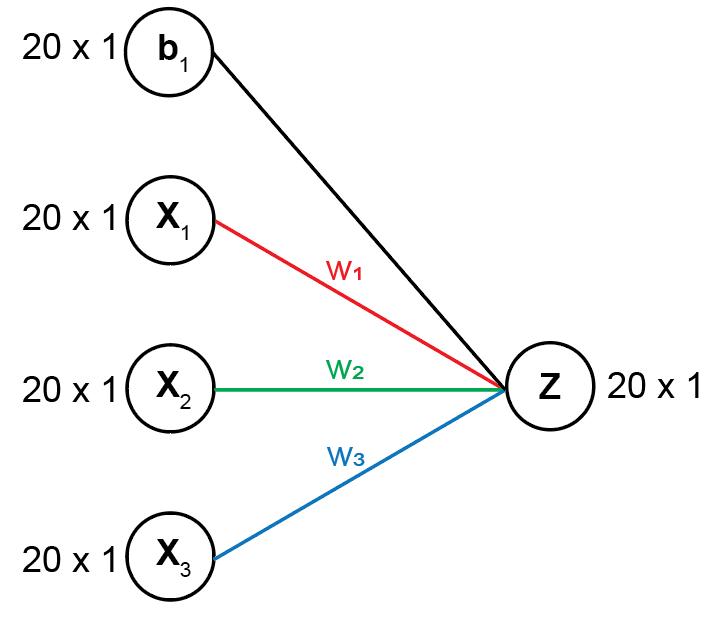

#### Analogy to linear regression

The formula to take a linear combination of predictors is shown below. The new features are stored in the variable `Z`.


$$Z=Xw^T +b$$


While this problem is slightly different from a linear regression problem in that we are solving for the output `Z` rather than using `X` and `Z` to estimate our coefficients, we actually have the same objective, and we're trying to estimate two parameters: 

- The **weights** ($w$), which is equivalent to the regression coefficients $\beta$

- The **bias** ($b$) values, which is equivalent to the intercept $\beta_0$. 

#### Impact of weights on the new feature `Z` generated by the neural network 

For now, let's see how the two parameters $w$ and $b$ affect the solution $Z$, and then plot the relationship between $X$ and $Z$. We'll take the linear combinations with 1 to 3 weights and biases of different values. 

% Initialize inputs using random numbers using a fixed random number generator (rng)
% for reproducibility
rng(2);
X = normrnd(0, 1, [20, 3])
b = randn([20, 1])

#### Solution using 1 weight vector

The following network diagram using 1 weight value is shown below:

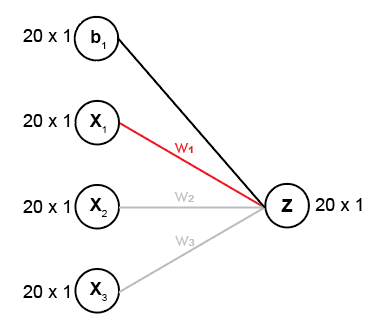

Which is equivalent to solving the following set of equations:


$$Z=X_1 w_1 +b$$


As you can see, the new feature $Z$ will most resemble $X_1$, shown in the scatter plot below.

% Weight vectors
w = [1, 0, 0] % Only 1 weight
Z1 = X * w' + b

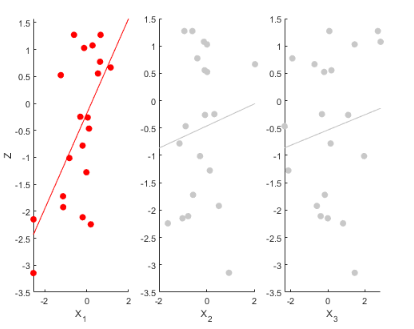

#### Solution using 2 weight vectors

If we include two weights, the network will look like the following diagram:

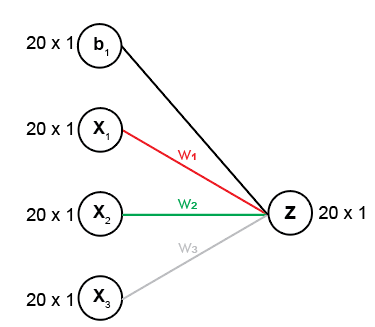

And the system of equations will look like the following:


$$Z=X_1 w_1 +X_2 w_2 +b$$


You will notice that there is a stronger correlation between the new feature $Z$ and $X_2$, as it is assigned a higher weight.

% Compute Z = x1w1 + x2w2 + x3w3 + b
w = [1, 2, 0] % 2 weights only
Z2 = X * w' + b

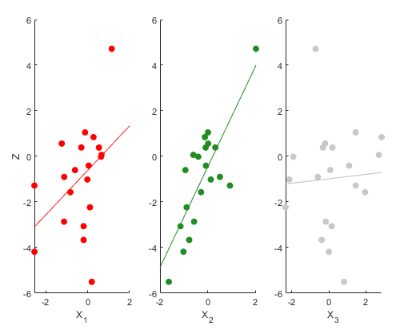

#### Solution using 3 weight vectors

Finally, let's include a fully connected hidden layer with all 3 weights.

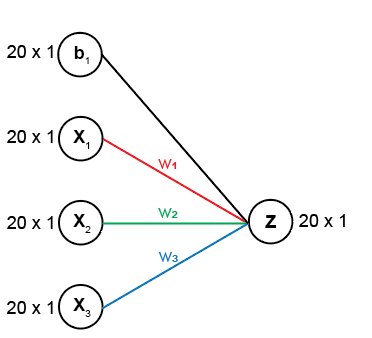

Where the complete set of linear equations to solve will be:


$$Z=X_1 w_1 +X_2 w_2 +X_3 w_3 +b$$


% Compute Z = x1w1 + x2w2 + x3w3 + b
w = [1; 2; -5]; % All 3 weights
Z3 = X * w + b

We have a new complex feature that is positively correlated with $X_1$ and $X_2$, but negatively correlated with $X_3$,

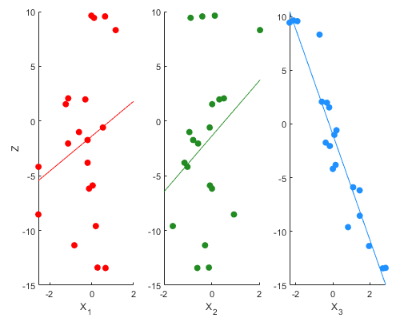

#### Overall impact of w on Z and key points

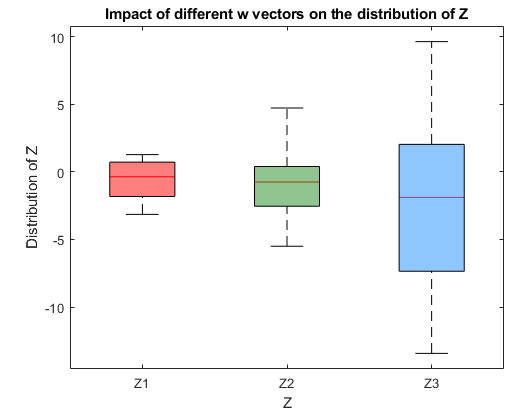

As you can see with the boxplot above, different combinations of weights dramatically the distribution of the final computed predictor `Z`, and creates more complex features`.` The weights are a really important parameter to tune in the model.

#### How do we initialize the weights and biases in practice?

Without knowing the true relationship between the predictor and response variables, we need to initialize the weight and bias parameters somehow. It turns out that[ intializing neural networks with small and random values for w and b is a better way](https://machinelearningmastery.com/why-initialize-a-neural-network-with-random-weights/) to train these parameters than setting them to all zero or one. We'll discuss why we need to initialize neural networks with small and random values for these parameters in the next lecture.  

### Non-linear transformations using an activation function

In this section, we'll discuss different ways to add non-linearity into the computed variable `Z`, and the advantages / disadvantages of each method.

#### The sigmoid activation function

One way to transform the data is to use the sigmoid activation function (aka logit transformation) to transform our data into probabilities with values ranging from [0, 1]. The formulation of the sigmoid activation function is simply:


$$\mathrm{sigmoid}\left(Z\right)=A=\frac{1}{1+e^{-Z} }$$


And the shape of the sigmoid distribution is shown below:

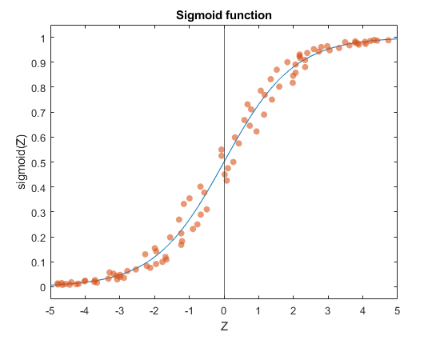

To access all the activation functions described in this lecture, we can use the `activationFnc` script provided in the project folder (documentation described below) to transform our values.

**Applying the sigmoid activation function to **`Z`** values obtained from changing **`w`

Let's see what happens when we apply the sigmoid activation function the three Z values we computed previously.

% Compute y using the Z1 cell array containing the results from using different w values
Z = [Z1, Z2, Z3] % Store all Z values in single array to perform 1 computation
A = activationFnc(Z, 'Sigmoid') % Scaled from 0 -> 1 using sigmoid activation function

In the plot below, I marked the decision boundary to be set to p = 0.5. As we add additional weight parameters, the transformed values tend to converge faster towards either 0 and 1. This feature of the sigmoid activation function is especially useful for binary classification, where we need to draw out a decision boundary between two classes.

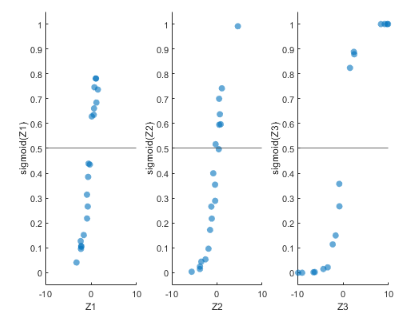

### Rectified linear units (ReLUs) 

While the `Sigmoid` activation function is easy to interpret and is simple to apply, there are issues with using it as an activation function:

- With each iteration, the $e^{-Z}$ term in the `sigmoid` function becomes infinitesimally small. When correcting our parameters in back propagation (covered in the next section), correcting these extremely small values result in slower updates. This is called the **vanishing gradient problem**, and is an issue when it comes to optimizing neural network parameters using gradient descent.

- Further, our values are between 0 and 1. This is not really useful for regression problems.

Thus, people have been turning to the ReLU as the preferred activation function, especially for more complex neural network architectures. The formulation of the **ReLU** is shown below, and is really simple:


$$\mathrm{ReLU}\left(z\right)=\left\lbrace \begin{array}{cc}
z & \mathrm{if}\;z>0\\
0 & \mathrm{if}\;z\le 0
\end{array}\right.$$


This basically sets negative values to 0, while leaving the original transformed value intact. The ReLU activation function has the following non-linear distribution shape:

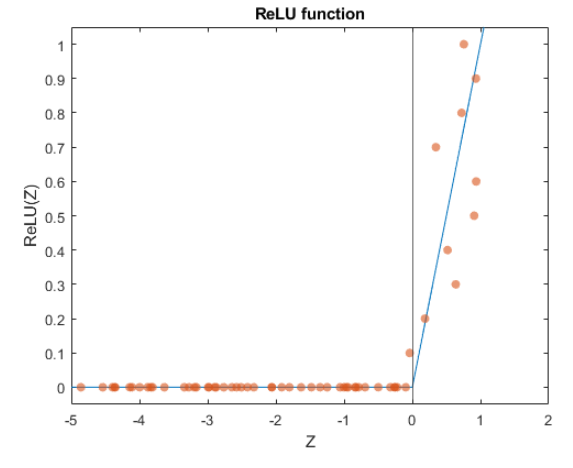

The ReLU has gained popularity in recent years because it takes care of the problems faced by the Sigmoid activation function, such as:

- The correction term in back propagation is not infinitesimally small. This rectifies the vanishing gradient problem.

- Because only a few neurons would be activated (negative values are all 0), this makes the model more efficient.

### Leaky rectified linear units (Leaky ReLUs) 

The ReLU does have its own set of problems, such as handling real negative values (since they're set to 0, the model will essentially ignore these values). 

There is an improved method of the ReLU: the** leaky ReLU**! Instead of setting to value to 0 for negative numbers, we'll scale the negative values using a small weight (usually this weight, which we'll denote as epsilon ($\varepsilon$) is set to 0.01). This will cause a smaller gradient to flow for the negative values, and thus improves our performance with negative numbers.

The formulation for the leaky ReLU is


$$\textrm{Leaky}\;\textrm{ReLU}\left(Z\right)=\left\lbrace \begin{array}{cc}
z & \textrm{if}\;z\;\textrm{is}\;\textrm{positive}\\
\varepsilon \cdot z & \textrm{if}\;z\;\textrm{is}\;\textrm{negative}
\end{array}\right.$$


The leaky ReLU has the following distribution shape:

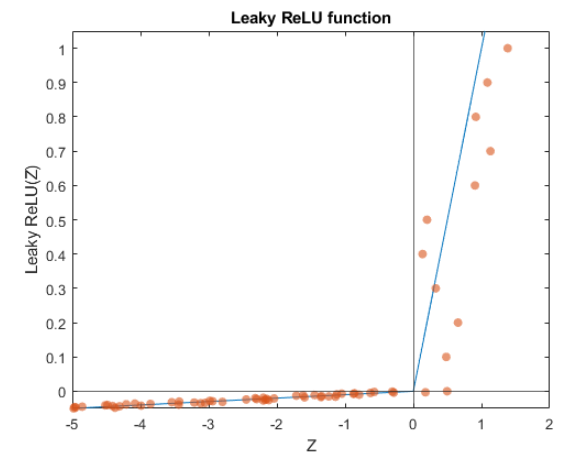

Now that we have covered a single round of combing features and adding non-linearity to the combined features, we have the tools to run a full round of forward propagation. 

### A single round of forward propagation

Let's now put all of these concepts together to run 1 round of forward propagation with **no hidden layer** using a breast cancer dataset built into MATLAB. Without the hidden layer, we're performing logistic regression using forward propagation!

#### Description of breast cancer dataset

The dataset can be called using the `load cancer_dataset `command, and a comprehensive description of the dataset can be found by typing in `help cancer_dataset`. We'll explore the dataset in the codeblock below

- The input is a matrix of 9 features from 699 biopsies. The features include attributes such as adhesion, cell size, and cell shape. These are stored in the `cancerInputs` variable. 

- The `cancerTargets` variable is a 2 x 699 matrix, where the first column corresponds to benign, and the the second column corresponds to malignant. Thus, we will perform binary classification.

clear all;
load cancer_dataset.mat
% View input dataset. Rows = features. Columns = observations
data = array2table(cancerInputs, ...
    "RowNames", {'Clump thickness', 'Uniform Cell size', ...
    'Uniform Cell shape', 'Adhesion', 'Single cell size', ...
    'Bare nuclei', 'Bland chromatin', 'Normal nucleoli', ...
    'Mitoses'})
% View target dataset. Rows = targets. Columns = observations
target = array2table(cancerTargets, ...
    "RowNames", {'Benign', 'Malignant'})

To save space in the code blocks in this lecture, we can use the accessory function `loadCancerData` to do the following steps:

- Load the dataset and target variables

- Transposes the datasets so that features and targets span columns

- Split the dataset and target variables into training and test datasets

- Standardize the input datasets to have a mean = 0 and standard deviation of 1. 

We'll use only 2 activation nodes in the hidden layer. Our (naive) hypothesis is that two activation nodes are able to capture the differences in a 2-class (binary) classification problem. We'll discuss a systematic way to choose the number of hidden nodes needed to optimize the performance of the neural network in the next lecture.

#### Intialize variables needed to run forward propagation

% Set seed for reproducibility
rng(2);

% Load the cancer data
[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData();

% Intialize the hyperparameters 
numberOutputNodes = 1; actFnc = 'Sigmoid';

% Intialize the weights and biases. w size should be number of features x number of activation nodes
w = randn([size(Xtrain, 2), numberOutputNodes])
% b size should be number of observations in training data x 1
b = randn([size(Xtrain, 1), 1])

#### Forward propagation

Let's now run forward propagation from the input layer to the output layer:

Z = Xtrain * w + b
% A is the final predicted value for this logistic regression model
ypred = activationFnc(Z, actFnc)


Now we need to now see how well our model performed using a cost function.

## Step 2: Evaluating the model fit using the cost function

Next, we need to evaluate how well our model has performed in it's initial pass through using a cost function. Because we are performing a binary classification problem, we can use the **Cross-Entropy cost function.**

### **Cross-Entropy cost function**

Recall the formulation for the Cross-Entropy cost function:


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -{y_{\textrm{train}} }^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-{y_{\textrm{train}} }^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


where $m$ are number of observations, $y_{\textrm{train}}$ is the response variable, and $y_{\textrm{pred}}$ is a vector of the predicted value from forward propagation. 

The **cost** value (`J)` can be computed using the `costFunction` function provided. The docstring is provided below:

% There will be two loss values: one for the malignant target and the other
% for the benign target
lossFunction = 'Log-Loss';
J = costFunction(Ytrain(:, 1), ypred, lossFunction)

Now that we have a cost value, we can start to optimize our neural network algorithm using backward propagation.

## Step 3: Optimizing `w` and `b` parameters using backward propagation

After computing the cost, we know how good or how bad our model performed overall. In neural networks, we need to tell the algorithm how to adjust the weight and bias parameters so that the cost goes down in the next iteration,  until we reach a stable minimum cost value. This process is called **back propagation**, and the optimization algorithm we use to update the weights and the biases is **gradient descent**. 

### Finding the gradients dW and db using back propagation

The objective of back propagation is to determine how much we should change `w` and `b` such that we minimize the cost. Thus, we need to find an expression that allows us to relate the cost back to the parameter`. `The **gradient**, or the values from solving partial differential equations of the cost with respect to W ($\frac{\vartheta J}{\vartheta W}$) and b ($\frac{\vartheta J}{\vartheta b}$) will tell us how much error a specific activation node contributes to the overall model error.

#### Intuition for back propagation 

Formulated below are the expressions needed to solve $\frac{\vartheta J}{\vartheta W}$ and  $\frac{\vartheta J}{\vartheta b}$ for each layer:

$\frac{\vartheta J}{\vartheta W}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta W}$ 

$\frac{\vartheta J}{\vartheta b}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta b}$ 

Let's consider the gradient $\frac{\vartheta J}{\vartheta W}$ (the same logic applies for $\frac{\vartheta J}{\vartheta b}$) and work backwards from the output layer to the input layer. There are three places where the model can go wrong: 

- From the output layer to the hidden layer ($\frac{\vartheta J}{\vartheta y}$). A natural expression to compute this error is computing $Y_{\mathrm{pred}} -Y_{\mathrm{train}}$.

- From the activation function ($\frac{\vartheta y}{\vartheta Z}$). This expression changes with different activation functions.

- From computing `A` with `w` ($\frac{\vartheta Z}{\vartheta W}$)

As you can see, each layer is chained together. Fortunately, because we know how the network is connected, we can figure out partial differential terms that will connect the cost to any given weight or bias parameter that needs to be adjusted to lower the cost. We won't go over the derivation for each term (honestly, you can probably just Google them), but in practice, we would work these differential equations individually and use the chain rule to compute the gradients. 

#### Derivative terms for back propagation in a logistic regression model

The following set of equations are used in our logistic regression model to compute the gradients for each parameter (denoted as `dw` and `db). `Because we're comparing our predictions directly against our training set, we don't have to compute the error from the activation function.

- 
$$\mathrm{dZ}=Y_{\mathrm{pred}} -Y_{\mathrm{train}} \;$$


- 
$$dW=\mathrm{dZ}\cdot {X_{\mathrm{train}} }^T \cdot \frac{1}{m}$$


- 
$$\;\mathrm{db}=$$
 
$$\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ}\right)$$


### Back propagation 

Now let's codify the expressions above to run back propagation. First we need to compute the error from the outermost layer: $\mathrm{dZ}=Y_{\mathrm{pred}} -Y_{\mathrm{train}} \;$

dZ = ypred - Ytrain(:, 1)

Next, we have to compute how much error our weights contributed to the overall error in proportion to `dZ.` $\frac{1}{m}$ normalizes our error term by the number of observations in the dataset: $dW=\mathrm{dZ}\cdot {X_{\mathrm{train}} }^T \cdot \frac{1}{m}$

m = size(Xtrain, 1) % m = number of observations in training set
dW = (1/m) .* (Xtrain' * dZ)

Finally, we compute the error in the bias term, which is the sum of the errors from the output layer normalized based on the number of observations in the data: 


$$\;\mathrm{db}=$$
 
$$\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ}\right)$$
 

db  = (1/m) .* sum(dZ, 2)

We have just completed the first iteration of back propagation, which relates the cost value J back to the parameters w and b. The last step we need to do is to update the weights and biases. We can do that using the **gradient descent** optimization algorithm.

### Optimizing parameters `W` and `b` using gradient descent

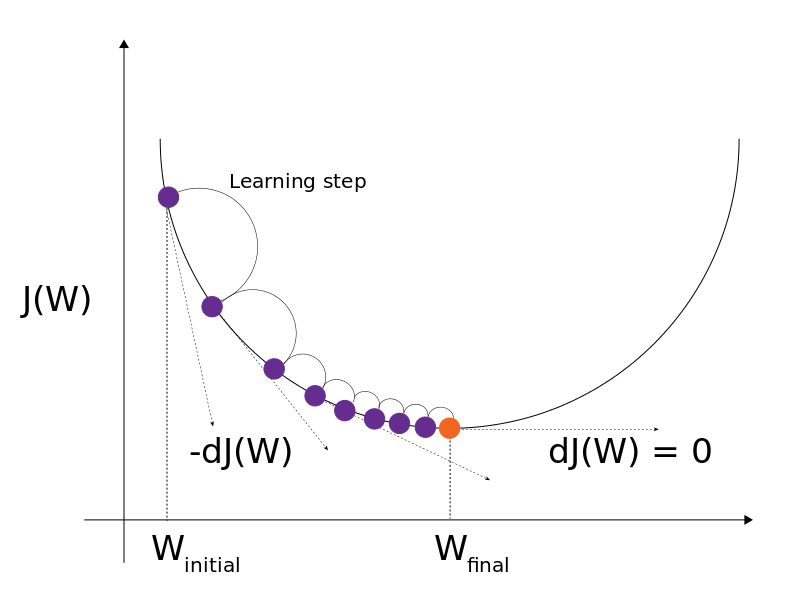

The objective of gradient descent is to minimize the cost by updating the parameters in the model. Because we have two parameters **W** and **b**, we have two update equations:


$$\begin{array}{l}
\mathrm{W}=\mathrm{W}-\left(\mathrm{learning}\;\mathrm{rate}\cdot \mathrm{dW}\right)\\
\mathrm{b}\;\;=\mathrm{b}\;\;-\left(\mathrm{learning}\;\mathrm{rate}\cdot \mathrm{db}\right)
\end{array}$$
 

where the learning rate hyperparameter is a positive constant value that controls how fast we move along the gradient. Further, `dW` and `db` are the gradients we computed from back propagation. 

We can perform gradient descent for `w` and `b` using the code below:

learning_rate = 0.05;
w = w - (learning_rate .* dW)
b = b - (learning_rate .* db)

We have just completed a single round of training and optimizing a logistic regression model using forward and back propagation. 

## Optimizing the logistic regression (NN model) using forward and backward propagation

Now that we did a single pass of forward and backward propagation with our logistic regression model, let's make an algorithm that uses all the components we described so far to optimize the two parameters `w` and `b` after 500 iterations. Note that in machine learning jargon, an iteration of both forward and backward prop is called an **epoch.**

First, let's re-initialize the variables we used in forward propagation, cost computation, and backward propagation:

% Intialize variables
epoch = 1000; learning_rate = 0.05; numberOfOutputNodes = 1; % Hyperparameters
m = size(Xtrain, 1);                               % Constant scalar
actFnc = 'Sigmoid';                                % Sigmoid activation function
w = randn([size(Xtrain, 2), numberOfOutputNodes]); % Number of Xtrain features x number of responses
b = randn([size(Xtrain, 1), 1]);                   % Number of observations

Next, we need to write an expression that will allow us to loop all three steps several times, while simultaneously updating the weights and biases after each iterations. 

for i = 1:epoch % Iterate 500 times
    % <1. Forward propagation>
    Z = Xtrain * w + b;
    ypred = activationFnc(Z, actFnc);
    
    % <2. Cost evaluation -> store the costs for plot>
    J(i) = costFunction(Ytrain(:, 1), ypred, 'Log-Loss');
    
    % <3. Back propagation>
    dZ = ypred - Ytrain(:, 1);
    dW = (1/m) .* (Xtrain' * dZ);
    db  = (1/m) .* sum(dZ, 2);
    
    % Gradient descent
    w = w - (learning_rate .* dW);
    b = b - (learning_rate .* db);
end

This is how we obtain the final trained model from forward and backward propagation. Note that we saved the cost for both class predictions during our `for` loop. Let's now plot the cost curve using the cost values `J` against the number of epochs to see how much the error decreased over each training period:

figure; hold on;
plot(1:epoch, J, 'color', 'r');
%plot(1:epoch, J(:, 2), 'color', 'g');
title('Cost with learning rate = 0.05'); %legend('Malignant', 'Benign');
xlabel('Number of epochs'); ylabel('Cost (J)');

The cost value of using a logistic regression model with forward and backward propagation begins to approach a minimum value around 500 epochs. How do the probability values we predict look?

ypred

Several values are very close to 0 or 1, indicating that we made a good classifier. Let's transform these probabilities to labels {1, 0} for each respective class, using a p = 0.5 as the decision boundary and compute the training accuracy for both classes:

% Label encoding for classification
ypred(ypred > 0.5) = 1; % If the probability is greater than 50%, set it to that class.
ypred(ypred < 0.5) = 0; % Otherwise, it is not that class.

% Compute training accuracy
train_accuracy = 1 - (sum(abs(ypred - Ytrain(:,1))) / m)

## Applying forward and backward propagation to another layer

Now that we constructed a logistic regression model that performs forward and backward propagation, we'll review each step, but this time, we'll be adding another node to our computations. 

%clear all; rng(2);
%[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData(); % Load the cancer data

### Forward propagation

First let's initialize some parameters and hyperparameters. This time, we'll have 4 parameters to compute: weights and biases between input and hidden layer `(w1, b1)`, and weights / biases between hidden and output layer `(w2, b2)`. 

In this example, we'll use two activation nodes in the hidden layer, just to see if two nodes are enough to separate the two classes in the neural net.

% Intialize the hyperparameters 
numberOfHiddenNodes = 2; actFnc = 'Sigmoid';

% Intialize the weights and biases. 
w1 = randn([size(Xtrain, 2), numberOfHiddenNodes]) % Size of w1 should be number of features x number of hidden nodes
b1 = randn(size(Xtrain, 1), 1) % Size should be number of obs x 1

Let's now 1 forward step from the input layer -> hidden layer.

Z1 = Xtrain * w1 + b1
A1 = activationFnc(Z1, actFnc)

Now that we have the transformed values stored in `A1`, we'll use this data and transform it 1 more time using forward propagation. First, let's initialize the weights and biases:

w2 = randn([size(A1, 2), size(Ytrain(:, 1), 2)]) % Size of w2 needs to be number of features in A1 x number of classes
b2 = randn(size(A1, 1), 1) % Size of b2 needs to be number of obs x 1

Finally, let's move 1 forward step from the hidden layer -> output layer. We'll use the same activation function we used in the previous step.

Z2 = A1 * w2 + b2

Because this is the last step, the final transformed dataset is our predicted value `ypred`

ypred = activationFnc(Z2, actFnc)

 That's forward propagation with 1 hidden layer. Next, we need to evaluate the cost.

### Cost evaluation

To evaluate the cost, let's use the cross entropy loss function:

LossFunction = 'Log-Loss';
J = costFunction(Ytrain(:, 1), ypred, LossFunction)

### Backward propagation

We went over the derivative terms for a single step of back propagation, and the computation from the outer layer to the hidden layer will be the same:

**Output layer to hidden layer: **

- 
$$\mathrm{dZ2}=Y_{\mathrm{pred}} -Y_{\mathrm{train}} \;$$


- 
$$d\mathrm{W2}=\mathrm{dZ2}\cdot {\mathrm{A1}}^T \cdot \frac{1}{m}$$


- 
$$\;\mathrm{db2}=\;\mathrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ2}\right)$$


First let's compute the error from the output $\mathrm{dZ2}=Y_{\mathrm{pred}} -Y_{\mathrm{train}}$

Ytrain = Ytrain(:, 1);
dZ2 = ypred - Ytrain

Next, we have to compute how much error our weights contributed to the overall error in proportion to `dZ.` $\frac{1}{m}$ normalizes our error term by the number of observations in the dataset: $d\mathrm{W2}=\frac{1}{m}\left(\mathrm{dZ}\cdot {\mathrm{A1}}^T \right)$

m = size(Xtrain, 1) % m = number of observations in training set
dW2 = (1/m) .* (A1' * dZ2)

Finally, we compute the error in the bias term, which is the sum of the errors from the output layer normalized based on the number of observations in the data: 


$$\;\mathrm{db2}=$$
 
$$\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ2}\right)$$
 

db2  = (1/m) .* sum(dZ2, 2)

**Hidden layer to input layer: **

The computation for the hidden layer to the input layer will essentially be the same, except for computing `dZ1.` This time, we need to compute the error generated from the activation function, `g'(Z1)`:

- 
$$\mathrm{dZ1}={\mathrm{W2}}^T \cdot \mathrm{Z2}\cdot g^{\prime } \left(\mathrm{Z1}\right)$$


- 
$$d\mathrm{W1}=\frac{1}{m}\left(\mathrm{dZ1}\cdot {X_{\mathrm{train}} }^T \right)$$


- 
$$\;\mathrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ1}\right)$$


As noted earlier, the activation function does have its own error term $g^{\prime } \left(\textrm{Z1}\right)$. For the sigmoid activation function derivative term: $g^{\prime } \left(\textrm{Z1}\right)\;=\left(1-{\textrm{A2}}^2 \right)$. 

However, the ReLU and leaky ReLU are nice in that there is no derivative! Instead, we can use the following rule sets:


$${g^{\prime } \left(Z\right)}_{\mathrm{ReLU}} =\left\lbrace \begin{array}{cc}
1 & \mathrm{if}\;Z>0\\
0 & \mathrm{if}\;Z\le 0
\end{array}\right.$$



$${g^{\prime } \left(Z\right)}_{\mathrm{Leaky}\;\mathrm{ReLU}} =\left\lbrace \begin{array}{cc}
1 & \mathrm{if}\;Z>0\\
\varepsilon  & \mathrm{if}\;Z\le 0
\end{array}\right.$$


Let's repeat the final step of back propagation, using the sigmoid activation function gradient: $\mathrm{dZ1}={\mathrm{W2}}^T \cdot \mathrm{Z2}\cdot g^{\prime } \left(\mathrm{Z1}\right)$

dZ1  = (w2 * dZ2') .* (1 - A1.^2)'

Next, let's compute dW1: $\frac{1}{m}\left(\mathrm{dZ1}\cdot {X_{\mathrm{train}} }^T \right)$

dW1  = (1/m) .* Xtrain' * dZ1'

Finally, we need to compute the cost for the biases: $\;\mathrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ1}\right)$

db1  = (1/m) .* sum(dZ1', 2)

### Gradient descent

Now that we computed the gradients, let's compute the updated weights and biases using gradient descent:

learning_rate = 0.05;
w2 = w2 - (learning_rate .* dW2)
b2 = b2 - (learning_rate .* db2)
w1 = w1 - (learning_rate .* dW1)
b1 = b1 - (learning_rate .* db1)

## Optimizing the neural network for the ovarian cancer data set

Now that we have all the steps required to train, evaluate, and optimize a shallow neural network, we would iterate this until the cost value reaches a minimum. 

To save space for iteratively running the shallow neural network we just wrote, we created an accessory function `SNN.` It it modularized to the three steps we performed: forward propagation, evaluating the cost, and back propagation. The docstring is provided below:

### Training and optimizing the shallow neural network

Let's now use this function to train a neural network using the ovarian cancer dataset:

%clear all; 
rng(2);

% 1. Split the dataset into a training and testing set using the accessory
% function.
[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData();
Ytrain = Ytrain(:, 1)

Ytrain =      1
     1
     1
     0
     1
     1
     0
     1
     1
     0


% 2. Specify hyperparameters to train the model and store in structure
hyperparameters.numOfActiveNodes = 2;
hyperparameters.alpha            = 0.05;
hyperparameters.epoch            = 1000;
hyperparameters.actFnc           = 'Sigmoid';
hyperparameters.randomstate      = 2;

% 3. Train the shallow neural network model
model = SNN(Xtrain, Ytrain, hyperparameters)

model = struct with fields:
     ypred: [559×2 double]
         J: [1000×2 double]
        w2: [2×2 double]
        b1: [559×1 double]
        w1: [9×2 double]
    actFnc: 'Sigmoid'


### Evaluating the costs

Now that we have a trained model, let's evaluate the results. First, let's plot the cost with respect to the number of iterations we made in the model:

figure; hold on;
epoch = 1000;
plot(1:epoch, model.J(:, 1), 'color', 'r');
%plot(1:epoch, model.J(:, 2), 'color', 'g');
title('Cost with learning rate = 0.05'); legend('Malignant', 'Benign');

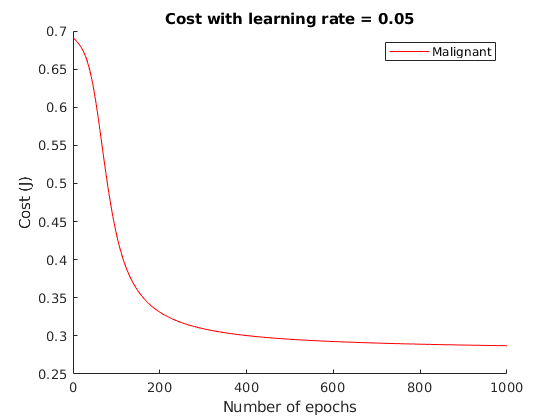

xlabel('Number of epochs'); ylabel('Cost (J)');

Without optimizing the hyperparameters we fed into the trained model, a minimum cost value approaches 0.28 when the learning rate is 0.05 under 500 epochs. What does our predicted values look like?

ypred = model.ypred

ypred =     0.9768    0.9768
    0.9768    0.9768
    0.9768    0.9768
    0.5000    0.5000
    0.9768    0.9768
    0.9768    0.9768
    0.5000    0.5000
    0.9768    0.9768
    0.9768    0.9768
    0.5000    0.5000


Some values are still close to 0.5. This indicates that our model has encountered the** vanishing gradient problem** described earlier. What most likely happened: the gradient was really small during the activation function transformation, and thus gradient descent could not correct the weights / biases. 

Let's transform these probabilities to labels {1, 0} for each respective class, using a p = 0.5 as the decision boundary and compute the training accuracy for both classes:

% Label encoding for classification
ypred(ypred > 0.5) = 1; % If the probability is greater than 50%, set it to that class.
ypred(ypred < 0.5) = 0; % Otherwise, it is not that class.

% Compute training accuracy
accuracy = 1 - (sum(abs(ypred - Ytrain)) / size(Ytrain, 1))

accuracy =     0.8157    0.8157


### Assessing model accuracy

#### Hold out

Next, let's use the test set to evaluate how our model does when seeing new data. To save space in the code blocks, we can use the `mdlPredict ac`cessory function, which takes the test data and outputs predictions for classification. The docstring is provided below:

ypred = mdlPredict(model, Xtest, Ytest, 'SNN')

Now that we have a prediction from our neural network, we can evaluate the model accuracy. Note that the values from `yred` are not necessarily 0 and 1. To transform our values back to our labels, we need to determine a decision boundary for classification. Let's use mean value of $y_{\textrm{pred}}$ as the decision boundary, where observations with a value greater than the $\textrm{mean}\left(y_{\textrm{pred}} \right)$ are assigned to be 1 (malignant). Otherwise, we'll assign that value to be 0 (benign). 

We'll also plot the confusion matrix and report the hold out accuracy using the `plotConfusionMatrix` code in the directory.

ypred =     0.5000    0.5000
    0.5000    0.5000
    0.9768    0.9768
    0.5000    0.5000
    0.9768    0.9768
    0.9768    0.9768
    0.5000    0.5000
    0.5000    0.5000
    0.9768    0.9768
    0.9768    0.9768


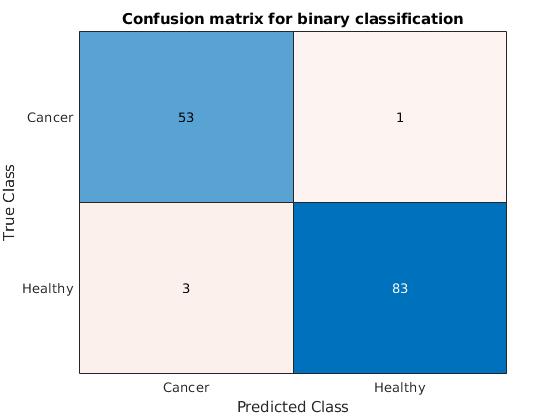

Summary = struct with fields:
           cm: [2×2 double]
    Precision: 0.9815
       Recall: 0.9464
     Accuracy: 0.9714
       Class1: 0.9815
       Class2: 0.9651
      F1score: 0.9636
          MCC: 0.9405


Hold-out malignant classification accuracy:0.98148


Summary = plotConfusionMatrix(Ytest(:, 1), ypred(:, 1))
disp(strcat('Hold-out malignant classification accuracy: ', ...
    string(Summary.Class1)))

disp(strcat('Hold-out benign classification accuracy: ', ...
    string(Summary.Class2)))

Hold-out benign classification accuracy:0.96512


disp(strcat('Hold-out average classification accuracy: ', ...
    string(Summary.Accuracy)))

Hold-out average classification accuracy:0.97143


#### k-fold cross validation

Of course, the hold out accuracy itself is not necessarily the best measure to evaluate the error from a machine learning model. Let's also run **k-fold cross validation** and obtain a relatively unbiased estimate of the test error. 

The `crossValidate` function is used to compute k-fold cross validation with two classes. The documentation for the function is shown below:

kfold = 10;
type  = 'SNN';
trainingSize = 0.8;
randomState = 3;

% Run cross validation
Summary = crossValidate(trainingSize, randomState, ...
                            hyperparameters, kfold, type);

% Plot confusion matrix
figure;
labels = {'Malignant', 'Benign'};
confusionchart(Summary.cm, labels, ...
    'Normalization', 'total-normalized')

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: {'Benign'  'Malignant'}

  Show all properties


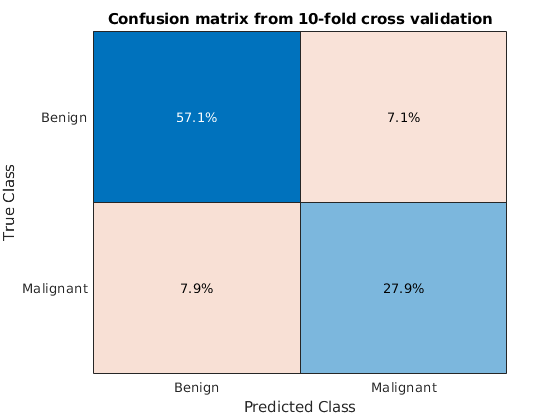

title('Confusion matrix from 10-fold cross validation');

%disp(strcat('10-fold CV malignant classification accuracy: ', ...
%    string(Summary.Class1)))

10-fold CV malignant classification accuracy:0.78


%disp(strcat('10-fold CV benign classification accuracy: ', ...
%    string(Summary.Class2)))

10-fold CV benign classification accuracy:0.88889


disp(strcat('10-fold CV average classification accuracy: ', ...
    string(Summary.Accuracy)))

10-fold CV average classification accuracy:0.85


## Issues in training neural networks

While neural networks are really popular for artificial intelligence research and applications, [there are issues with training them](https://machinelearningmastery.com/why-training-a-neural-network-is-hard/). 

### Initializing values for w and b

Earlier, we initialized our values for w and b to be small random numbers. Is this the best choice for w and b? We discuss 2 alternative cases that are different from our random intiialization of small numbers: if w and b are all zeros and all ones.

#### Setting w and b to be all zeros

We'll go back to our synthetic dataset with 50 observations and 6 features and plot the results when w and b are all zero.

rng(2);

Xtrain = normrnd(0, 1, [50, 6]);

w = [0, 0, 0, 0, 0, 0];
b = zeros([50, 1]);
Z = Xtrain * w' + b;

figure;
plot(Z); hold on; plot(activationFnc(Z, 'Sigmoid')); hold off;
legend({'Z', 'Sigmoid(Z)'});
ylim([-0.1 0.6]);
xlabel('Observations'); ylabel('Z or sigmoid(Z)');

If the values are all zeros, the neural network stops learning the features - they will be stuck at Z = 0 and A = 0.5 during every iteration.

#### Setting w and b to be all ones

Let's see what happens when we set w and b to be all ones:

w = [1, 1, 1, 1, 1, 1];
b = ones([50, 1]);
Z = Xtrain * w' + b;

figure;
plot(Z); hold on; plot(activationFnc(Z, 'Sigmoid')); hold off;
legend({'Z', 'Sigmoid(Z)'});
xlabel('Observations'); ylabel('Z or sigmoid(Z)');

As you can see, our features (blue) end up being transformed to log-odds in the range [0, 1] (red) by the activation function. Thus, the neural network algorithm essentially becomes a logistic regression classifier when using the sigmoid activation function and the biases are all equal to 1.

#### Symmetry breaking

**Symmetry breaking** is a phenomenon where very small, random fluctuations in a system are able to influence the outcome. By randomly initializing w and b to be small random numbers, we don't break the algorithm from the beginning and we allow the neural network to approach a better solution through back propagation / gradient descent.

### Overfitting

Recall that the underlying objective in machine learning is to build a model that balances the model's ability to minimize bias and variance (the **bias-variance tradeoff**). Neural networks are complex models and are susceptible to overfitting noise in a dataset. 

To address this potential issue, one potential solution is to use **regularization (ie Ridge or LASSO)** in the loss function and gradients. Recall that the regularized term is a function of the coefficients (the most important ones being weights) and a tuning factor $\lambda$. Regularization reduces overfitting by penalizing the weights. 

The following code imposes ridge regularization on the cross entropy loss function and subsequent back propagation for our shallow neural network:

Note that `lambda` is the ridge regularization term, and would be another hyperparameter we have to tune if we decide to regularize our neural network. 

### Data scaling

While neural networks can capture trends in complex / non-standardized datasets, there are several advantages to train using standardized data:

- We reduce the training time because we're examining a smaller range of values and thus reducing the time it takes for the weights to converge to an optimal value.

- We reduce the change of getting stuck in a local optima when computing the loss due to chance by minimizing the dynamic range of the data.

Recall that there are two common ways to scale our data depending on how we wish to interpret each feature: the **Z-score method**, and the **min-max scaling method**. The z-score method will ensure that each value is scaled to have a mean of 0 and standard deviation of 1. 


$$X_{z-\textrm{score}} =\frac{X_{\textrm{ij}} -\textrm{mean}\left(X_j \right)}{\textrm{std}\left(X_j \right)}$$


While useful, scaling in this manner can produce results that don't necessarily reflect true values, especially if our feature is composed of only positive values. In those cases, min-max scaling can actually be better, where we scale the data point from a value of 0 to 1 for values that are only positive:


$$X_{\min -\max } =\frac{X_{\textrm{ij}} -\min \left(X_j \right)}{\max \left(X_j \right)-\min \left(X_j \right)}$$


### Determining the best neural network structure to use.

Recall that we've been using a naive approach to determining the number of activation nodes in our neural network, where we assumed two activation nodes are best because we're trying to split the data into two classes. While it's a good starting point, it's another assumption we're imposing on the model.

To determine the best number of activation nodes to use for either a single layer or `L` layers, we need to optimize this hyperparameter in a systematic way. One way to do so is to run k-fold cross validation, and see which number of activation nodes best improves the accuracy / minimzes the error from the model. 

## Hyperparameter tuning

Hyperparameter tuning is finding the best set of hyperparameters that will optimize the k-fold cross validation accuracy of our model without overfitting. This is not a trivial problem, as the number of possible solutions explode combinatorially with the number of parameters we wish to tune. 

### Complete Grid Search

So far, we have discussed the following set of hyperparameters:

- Number of activation nodes for each layer (Number of potential parameters: L layers * n nodes).

- The learning rate (Number of potential parameters: 100, assuming we sample [0.01, 1] in 0.01 increments. Estimate is higher if we want to explore lower / higher values).

- The number of epochs / iterations (Number of potential parameters: 500).

- The activation function (Number of potential parameters: 3).

n = 100 * 100 * 500 * 3;
disp("Number of posible parameter combinations to sample: " + string(n))

There are about $15,000,000$ different possible combinations from 4 parameters to sample, not including the training/test size and optimizing the number of k-folds in cross validation. 

A **complete grid search** explores every single combination. While the code is shown for running an exhaustive grid search, another (preferred) method that balances the amount of time searching for an optimal model and model performance is a random grid search, discussed below.

To run a comprehensive grid search, we can use the following code which uses a custom script called `CompleteGridSearchCV`:

### Random Grid Search

A **random grid search** takes in a random combination of hyperparameters to find the best set of hyperparameters to use. There are several benefits to randomized grid search, namely that the search time is decreased by A LOT. Instead of searching every single combination of parameters, we can chose the number of times we want to run our random search (ie 1000 times) to get the best hyperparameters. Additionally, [Bergestra and Bengio, 2012](http://www.jmlr.org/papers/volume13/bergstra12a/bergstra12a.pdf) found that random search can perform just as well, if not better, than a grid search. 

To run a random grid search, we can use the following code, which uses a custom script `RandomGridSearchCV`:

## Benchmarking against a logistic regression classifier

A neural network is a more flexible model compared to other models, in that it performs both linear and nonlinear transformations on the data. Let's see how well our shallow neural network performs against a logistic regression classifier, a less flexible model that only performs nonlinear transformations on the dataset.  

### Logistic regression

Recall that the formulation for a logistic regression problem is 1) applying the sigmoid function to our linear equation $\hat{f} \left(x\right)=X^T \beta$ to transform the values to log-odds, then 2) estimating $\beta$ from the data $X$ such that it maximizes the likelihood of estimating  a value $\hat{y}$ close to the true value of $y$.

Thus the equation we're trying to solve for a logistic regression problem is formulated below:


$$\hat{f} \left(x\right)=\frac{1}{1+e^{-X^T \beta } }$$


We'll be using the `mnrfit` function to get our $\beta$ coefficients, then run 10-fold cross validation. 

clear all;
rng(2);

kfold = 10;
type = 'Logistic';
trainingSize = 0.8;
randomState = 2;
logisticCM = crossValidate(trainingSize, randomState, ...
                            [], kfold, type);
% Plot confusion matrix
figure;
labels = {'Malignant', 'Benign'};
confusionchart(logisticCM.cm, labels, ...
    'Normalization', 'total-normalized');
title('Confusion matrix from 10-fold cross validation');
disp(strcat('10-fold CV malignant classification accuracy: ', ...
    string(logisticCM.Class1)))
disp(strcat('10-fold CV benign classification accuracy: ', ...
    string(logisticCM.Class2)))
disp(strcat('10-fold CV average classification accuracy: ', ...
    string(logisticCM.Accuracy)))

### Shallow neural network

Let's re-train our neural network and compare the two results

clearvars -except logisticCM Xtrain Ytrain Xtest Ytest;
rng(2);

% Set the hyperparameters to use
hyperparameters.numOfActiveNodes = 82;
hyperparameters.alpha = 0.91;
hyperparameters.epoch = 64;
hyperparameters.actFnc = 'Leaky ReLU';
hyperparameters.randomstate = 2;

% Perform 10-fold cross validation
kfold = 10;
type = 'SNN';
trainingSize = 0.8;
randomState = 2;

nnCM = crossValidate(trainingSize, randomState, ...
                            hyperparameters, kfold, type);
% Plot confusion matrix
figure;
labels = {'Malignant', 'Benign'};
confusionchart(nnCM.cm, labels, ...
    'Normalization', 'total-normalized');
title('Confusion matrix from 10-fold cross validation');
disp(strcat('10-fold CV malignant classification accuracy: ', ...
    string(nnCM.Class1)))
disp(strcat('10-fold CV benign classification accuracy: ', ...
    string(nnCM.Class2)))
disp(strcat('10-fold CV average classification accuracy: ', ...
    string(nnCM.Accuracy)))

### Results

The shallow neural network slightly outperforms the logistic regression classifier with the given set of hyperparameters. 

At this point, or even earlier in the lecture, you may have been wondering how we selected the hyperparameters to use in the examples above. Currently, we have not explored a systematic way to determine which hyperparameters to use. We will discuss two strategies in the section below.

## Summary

In this lecture, we trained a shallow neural network on breast cancer imaging data and evaluated its performance. Additionally, we discussed how training a neural network can be challenging, and some common pitfalls. Finally, we benchmarked the neural network against a logistic regression classifier, and found that the neural network outperformed the logistic regression classifier.

## Useful reading and references

- A [generalized tutorial for learning about neural networks](https://medium.com/datathings/neural-networks-and-backpropagation-explained-in-a-simple-way-f540a3611f5e) that is language-agnostic.

- The [various flavors of neural networks](https://towardsdatascience.com/the-mostly-complete-chart-of-neural-networks-explained-3fb6f2367464), and how they are currently being used in real-world settings.

- Heuristics on deciding [how many hidden layers and activation nodes](https://machinelearningmastery.com/how-to-configure-the-number-of-layers-and-nodes-in-a-neural-network/) to initialize in a neural network.

- [Other activation functions, their usage, and generalizations about pros/cons](https://medium.com/@himanshuxd/activation-functions-sigmoid-relu-leaky-relu-and-softmax-basics-for-neural-networks-and-deep-8d9c70eed91e).

- [Andrew Ng's CS229 deep learning notes ](http://cs229.stanford.edu/notes/cs229-notes-deep_learning.pdf)for a more in-depth understanding of the mathematics and algorithms for constructing neural networks from scratch.

- The [deep learning specialization on Coursera](https://www.coursera.org/specializations/deep-learning) (also taught by Andrew Ng and others at [deeplearning.ai](https://www.deeplearning.ai/)). It consists of 5 courses, all on deep learning and optimizing these models. The course is taught in Python with the specific usage of the `numpy` and `scipy` libraries.

- [Deep Learning](http://www.deeplearningbook.org/) by Ian Goodfellow and Yoshua Bengio - two pioneers in modern deep learning. The book covers 1-2 semester's worth of material for not the basics of constructing and applying deep neural networks, but more cutting-edge techniques in Artificial Intelligence